# Demo 2: przetwarzanie wstępne (preprocess)

Skrypt odtwarza krok po kroku funkcję preprocess: korekcję nierównomiernego oświetlenia oraz wyznaczanie obszaru zainteresowania (ROI). Na końcu wynik jest porównywany z wywołaniem samej funkcji.

## Konfiguracja

W Live Editorze mfilename wskazuje na plik tymczasowy w /tmp, dlatego sprawdzamy kilka możliwych lokalizacji skryptu i wybieramy tę, dla której istnieje folder data/ dwa poziomy wyżej.

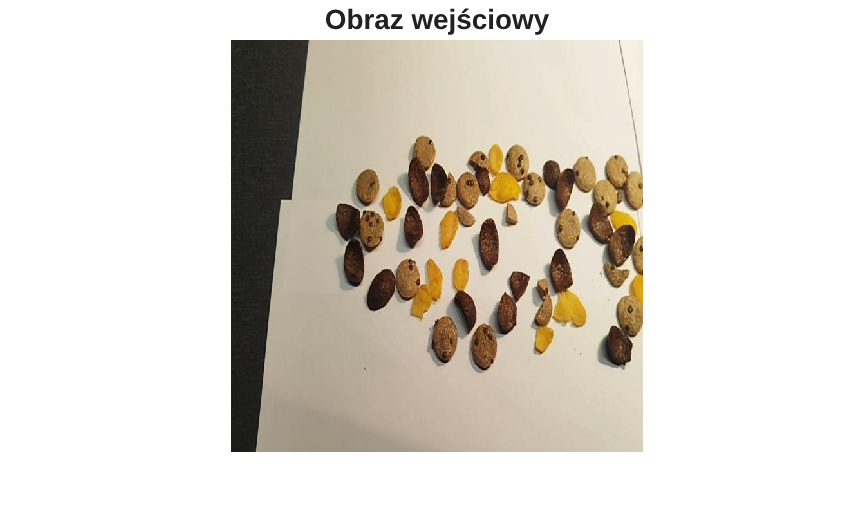

candidates = string(fileparts(mfilename("fullpath")));
try
    candidates(end+1) = fileparts(matlab.desktop.editor.getActiveFilename);
catch
end
candidates(end+1) = pwd;
candidates = candidates(candidates ~= "");
ok = arrayfun(@(d) isfolder(fullfile(d, "..", "..", "data")), candidates);
assert(any(ok), "Nie znaleziono folderu data/. Ustaw Current Folder na segmentation/demo.")
demoDir = candidates(find(ok, 1));
segDir  = fileparts(demoDir);
addpath(segDir);
dataDir = fullfile(segDir, "..", "data", "Mlekolaki.v3i.coco");

% Obraz z cieniem w lewym dolnym rogu i ciemnym materiałem z lewej strony.
% Można podmienić na dowolny inny plik ze zbioru.
f = dir(fullfile(dataDir, "test", "Video2_mp4-218_jpg*.jpg"));
Iraw = imread(fullfile(f(1).folder, f(1).name));
figure; imshow(Iraw); title("Obraz wejściowy")

## Część A: korekcja oświetlenia

Papier powinien być jednolicie biały, ale jest jaśniejszy w jednych miejscach i ciemniejszy w innych. Szacujemy więc samo oświetlenie (jasność papieru w każdym miejscu) i dzielimy przez nie obraz.

## Krok A1: zmniejszenie obrazu

Oświetlenie zmienia się powoli, więc wystarczy je szacować w połowie rozdzielczości, co przyspiesza kolejne operacje.

I = im2double(Iraw);
small = imresize(I, 0.5);
size(small)

ans =    320   320     3


## Krok A2: zamknięcie morfologiczne

Zamknięcie (dylatacja, potem erozja) dużym dyskiem zastępuje ciemne obiekty mniejsze od dysku jasnością otaczającego papieru. Zostaje sam "papier" z jego cieniami.

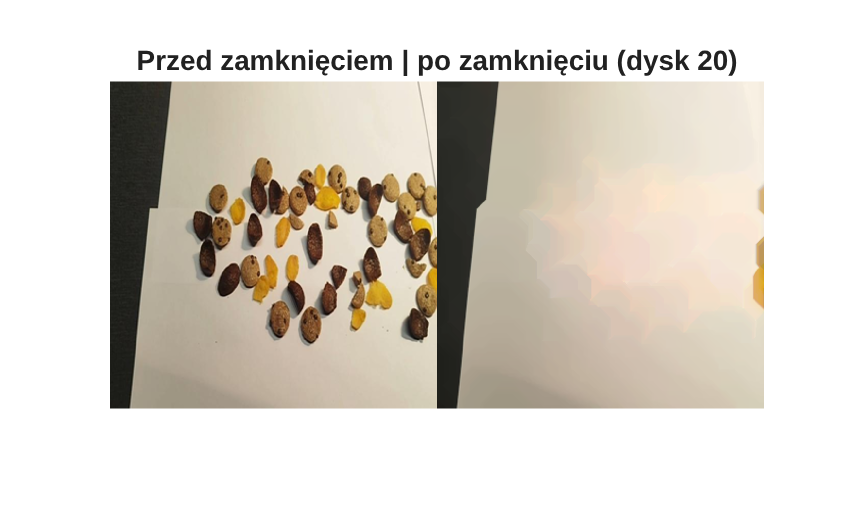

bgClosed = imclose(small, strel("disk", 20));
figure; montage({small, bgClosed}, "Size", [1 2])
title("Przed zamknięciem | po zamknięciu (dysk 20)")

## Krok A3: wygładzenie Gaussem

Zamknięcie zostawia kanciaste artefakty; filtr Gaussa daje gładką mapę oświetlenia.

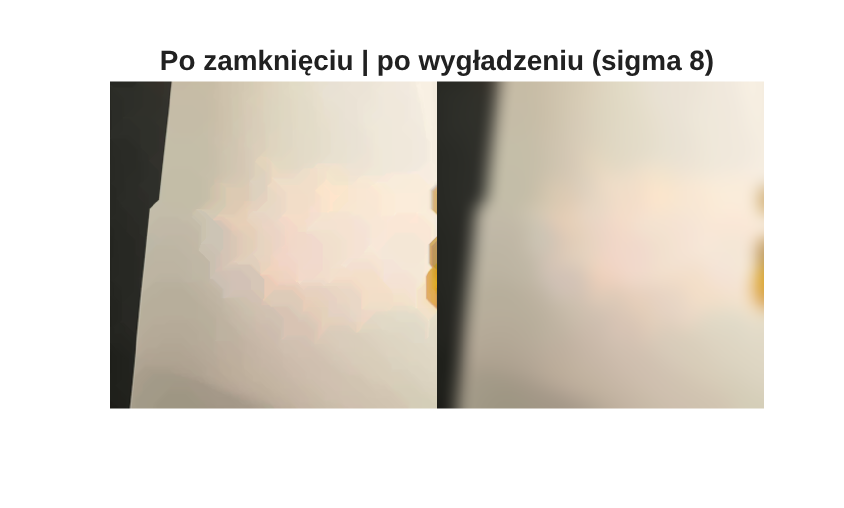

bgSmooth = imgaussfilt(bgClosed, 8);
figure; montage({bgClosed, bgSmooth}, "Size", [1 2])
title("Po zamknięciu | po wygładzeniu (sigma 8)")

## Krok A4: powrót do pełnej rozdzielczości

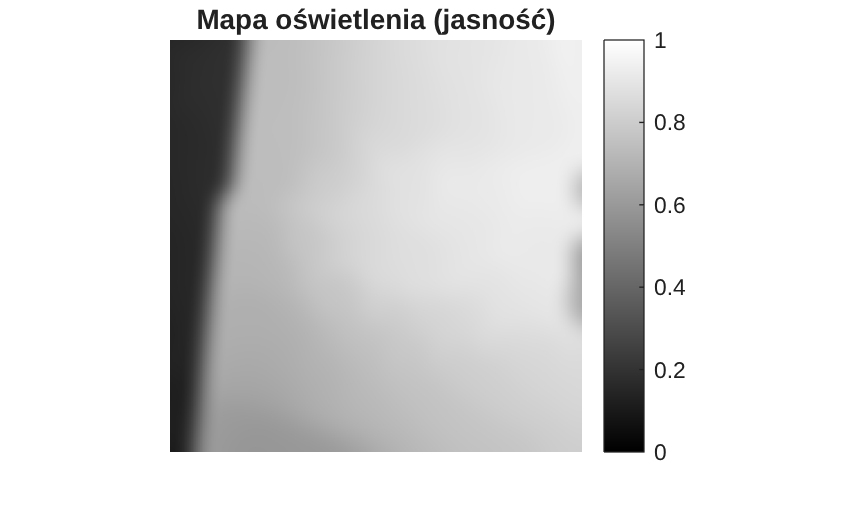

bg = imresize(bgSmooth, [size(I, 1) size(I, 2)]);
figure; imshow(rgb2gray(bg)); colorbar
title("Mapa oświetlenia (jasność)")

## Krok A5: dzielenie przez oświetlenie

Obraz dzielony jest przez mapę oświetlenia i skalowany do 0.9, więc papier wszędzie ma jasność około 0.9. max(bg, 0.05) chroni przed dzieleniem przez zero w bardzo ciemnych miejscach.

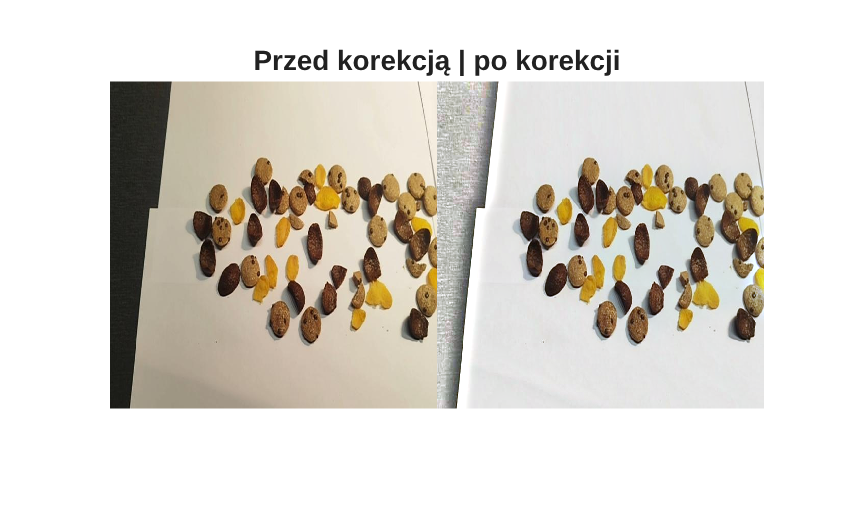

J = im2uint8(min(1, 0.9 * I ./ max(bg, 0.05)));
figure; montage({Iraw, J}, "Size", [1 2])
title("Przed korekcją | po korekcji")

Profil jasności wzdłuż jednego wiersza: po korekcji tło jest płaskie, a spadki odpowiadają tylko obiektom.

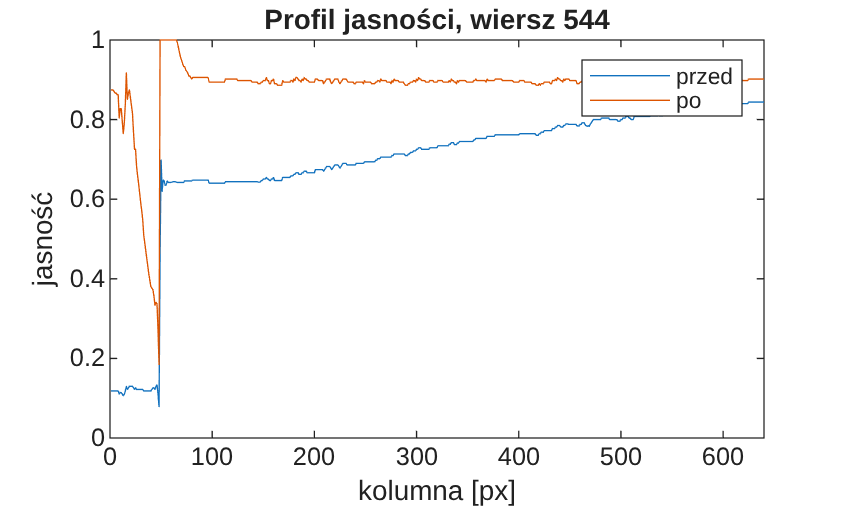

row = round(0.85 * size(I, 1));
grayBefore = rgb2gray(I);
grayAfter  = im2double(rgb2gray(J));
figure
plot(grayBefore(row, :), "DisplayName", "przed"); hold on
plot(grayAfter(row, :), "DisplayName", "po"); hold off
xlabel("kolumna [px]"); ylabel("jasność"); legend; ylim([0 1])
title(sprintf("Profil jasności, wiersz %d", row))

## Część B: obszar zainteresowania (ROI)

Poza kartkami papieru widać ciemny materiał lub stół. Kolorem przypomina on czekoladę, więc trzeba go wykluczyć.

## Krok B1: progowanie ciemnych pikseli

Piksele o jasności poniżej 0.3. Łapie to materiał, ale też ciemne przekąski (choco).

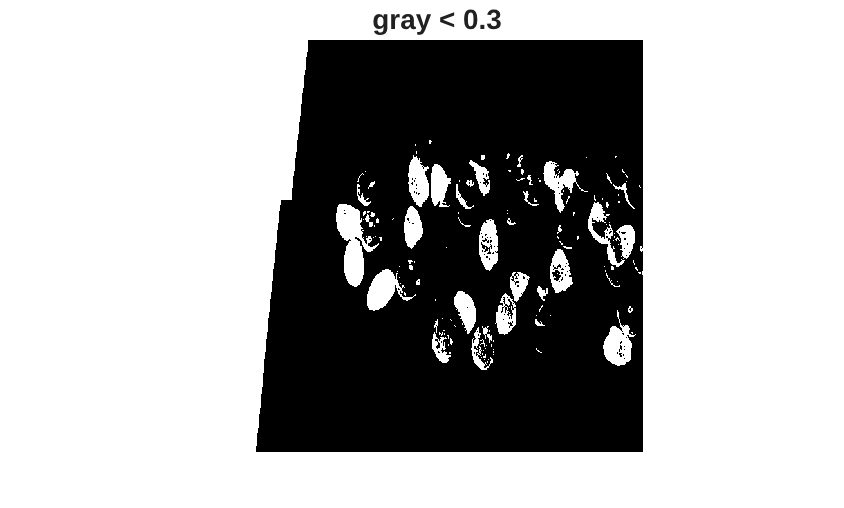

gray = rgb2gray(I);
dark0 = gray < 0.3;
figure; imshow(dark0); title("gray < 0.3")

## Krok B2: otwarcie dużym dyskiem

Otwarcie (erozja, potem dylatacja) dyskiem szerszym niż przekąska usuwa małe ciemne obiekty. Zostają tylko duże ciemne obszary, czyli tło poza papierem.

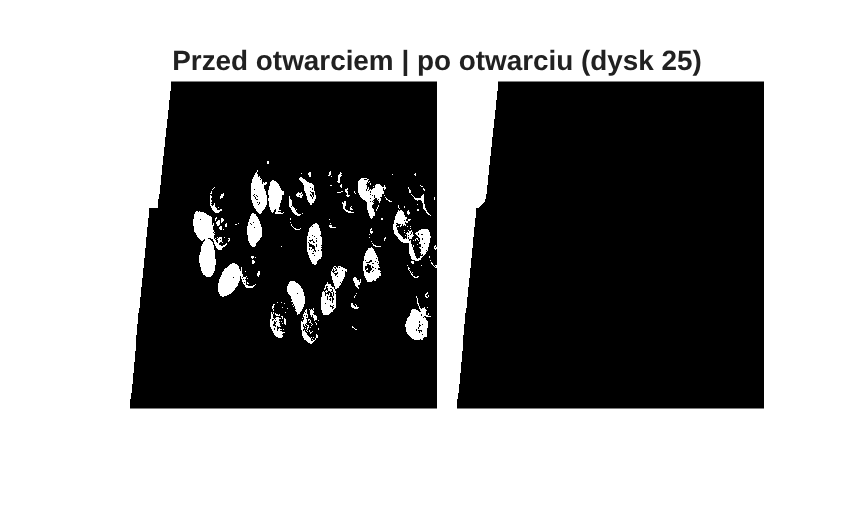

dark = imopen(dark0, strel("disk", 25));
figure; montage({dark0, dark}, "Size", [1 2])
title("Przed otwarciem | po otwarciu (dysk 25)")

## Krok B3: poszerzenie i negacja

Lekka dylatacja odsuwa ROI od krawędzi kartki, gdzie są cienie. ROI to wszystko oprócz ciemnych obszarów.

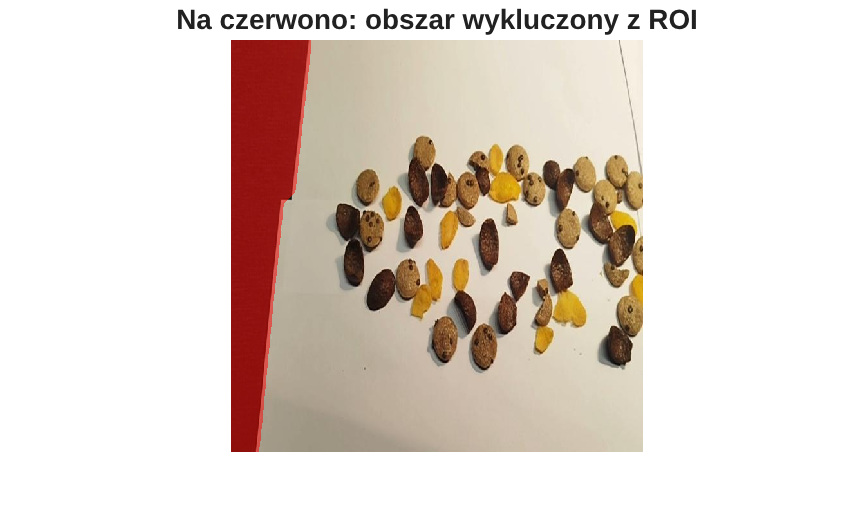

roi = ~imdilate(dark, strel("disk", 6));
figure; imshow(labeloverlay(Iraw, ~roi, "Colormap", [1 0 0], "Transparency", 0.5))
title("Na czerwono: obszar wykluczony z ROI")

## Sprawdzenie: porównanie z funkcją preprocess

Wynik krok po kroku powinien być identyczny z wynikiem funkcji.

[J2, roi2] = preprocess(Iraw);
fprintf("J identyczne: %d, roi identyczne: %d\n", isequal(J, J2), isequal(roi, roi2));

J identyczne: 1, roi identyczne: 1
